# **HW11**

## Q1 [CORRECT]

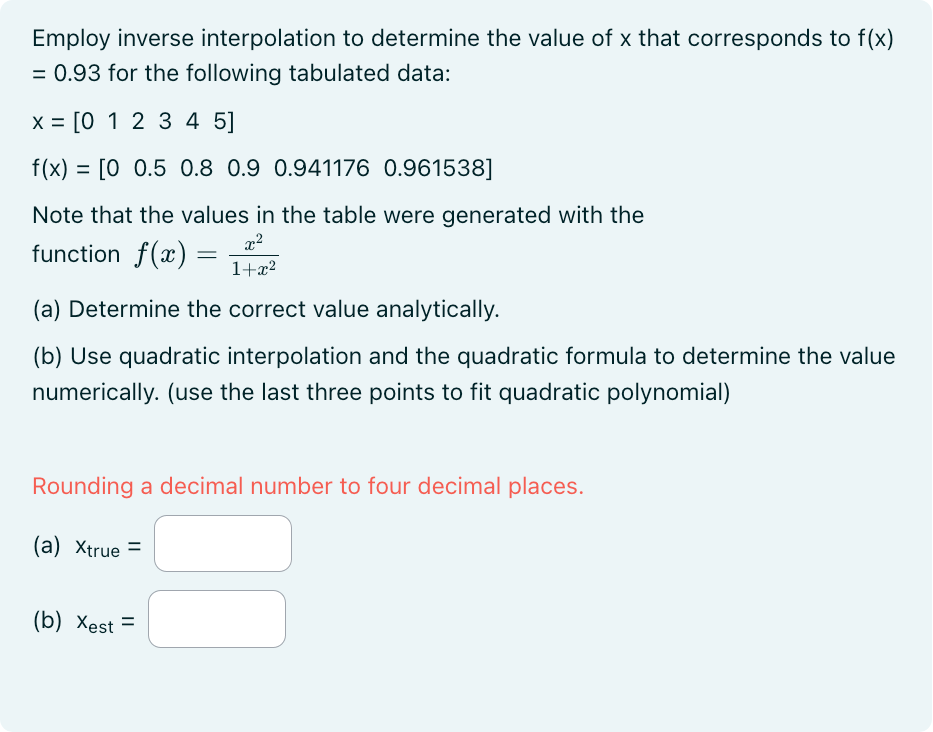

a)

xx = [0  1  2  3  4  5];
yy = [0  0.5  0.8  0.9  0.941176  0.961538];
ytest = 0.93
q1_xpredinv = sqrt(ytest / (1 - ytest))

b)

xx2 = [3 4 5];
yy2 = [0.9  0.941176  0.961538];
p2 = polyfit(xx2, yy2, 2)
a = p2(1)
b = p2(2)
c = p2(3) - ytest
x1 = (-b + sqrt(b^2 - (4*a*c))) / (2*a)
x2 = (-b - sqrt(b^2 - (4*a*c))) / (2*a)
% ans = x1 = 3.6730

## Q2 [CORRECT]

### **2.1**

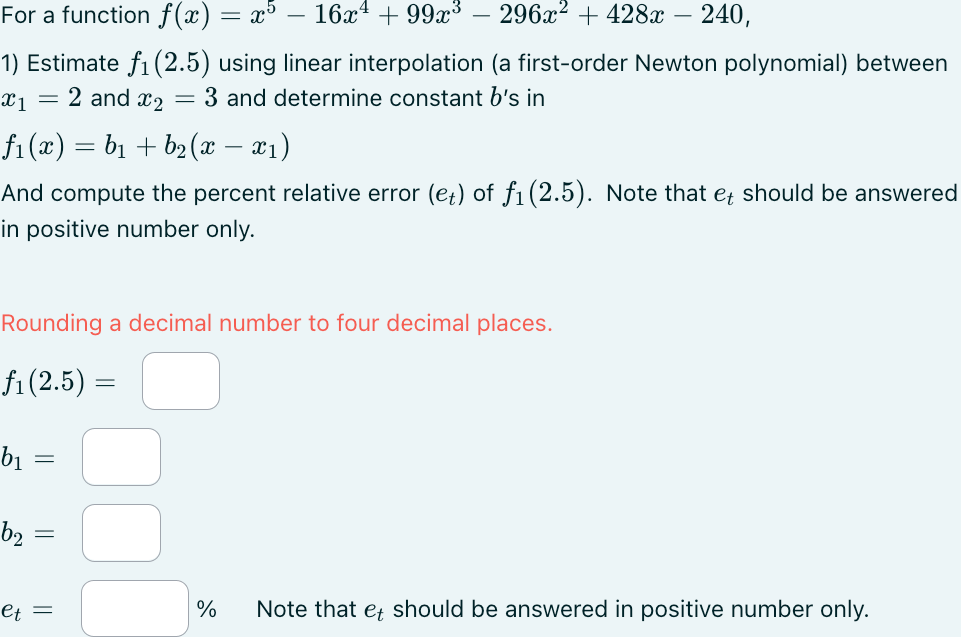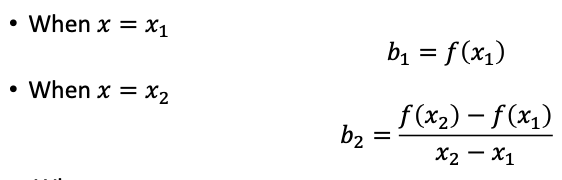

NOTE: $f_1 \left(2\ldotp 5\right)$ is NOT `ftrue` (look at the expression given above)

xtest = 2.5;
f = @(x) x.^5 - (16.*x.^4) + (99.*x.^3) - (296.*x.^2) + (428.*x) - 240;
ftrue = f(xtest);
x = [2 3];
y = f(x);
y1newttest = Newtint(x, y, xtest)
et = abs((ftrue - y1newttest) / ftrue) * 100

### 2.2

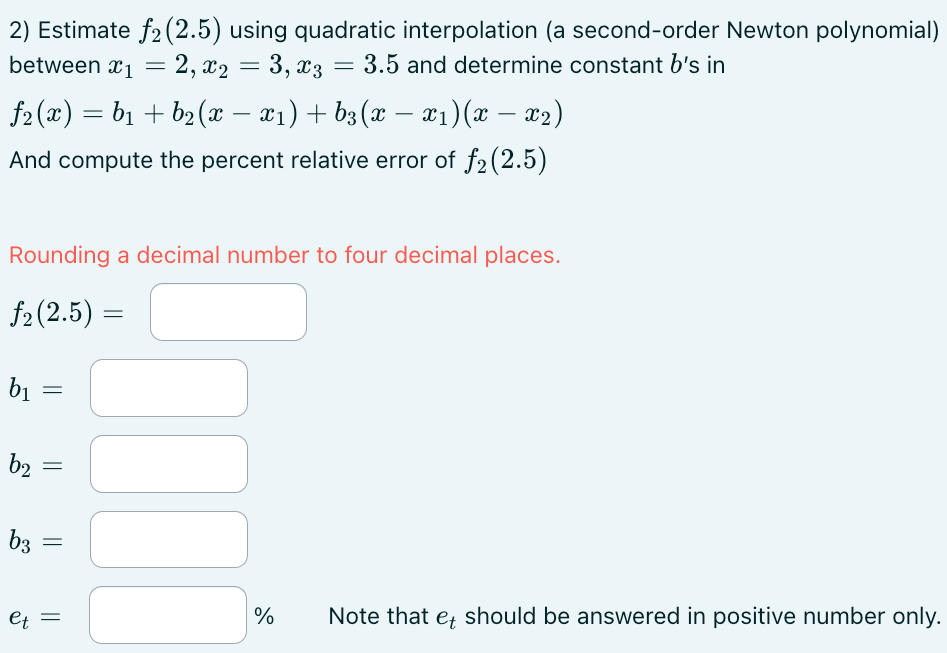

NOTE: $f_2 \left(2\ldotp 5\right)$ is NOT `ftrue` (look at the expression given above)

xtest = 2.5;
x = [2 3 3.5];
f = @(x) x.^5 - 16*x.^4 + 99*x.^3 - 296*x.^2 + 428*x - 240;
y = f(x);
y2newttest = Newtint(x, y, xtest)
et2 = abs((ftrue - y2newttest) / ftrue) * 100

### 2.3

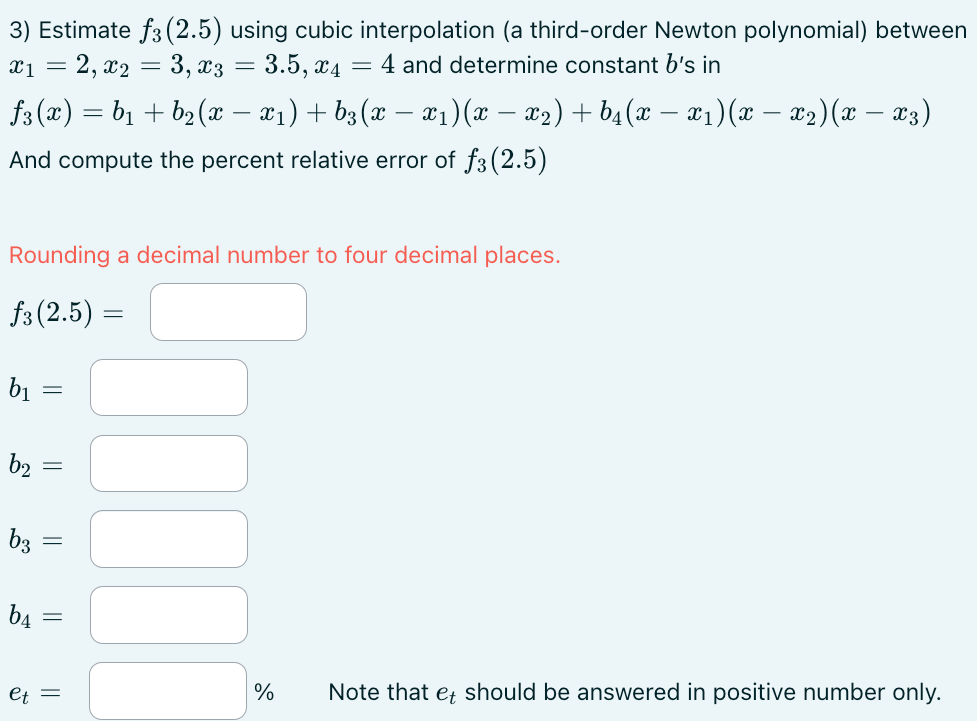

NOTE: $f_3 \left(2\ldotp 5\right)$ is NOT `ftrue` (look at the expression given above)

x = [2 3 3.5 4];
y = f(x);
y3newttest = Newtint(x, y, xtest)
et3 = abs((ftrue - y3newttest) / ftrue) * 100

## Q3 [CORRECT]

***Edit this line only for answering the ***$L_i$**.**

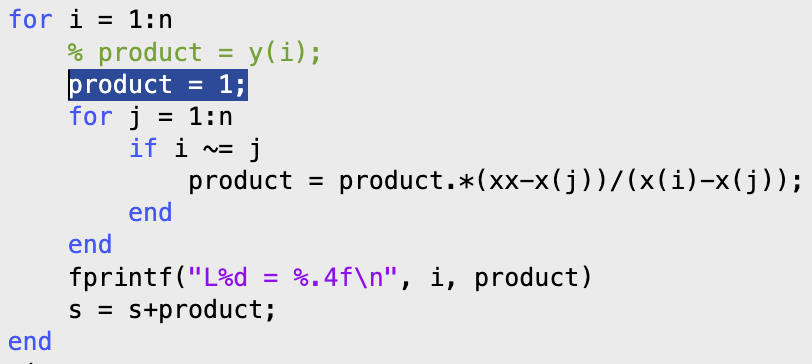

### **3.1**

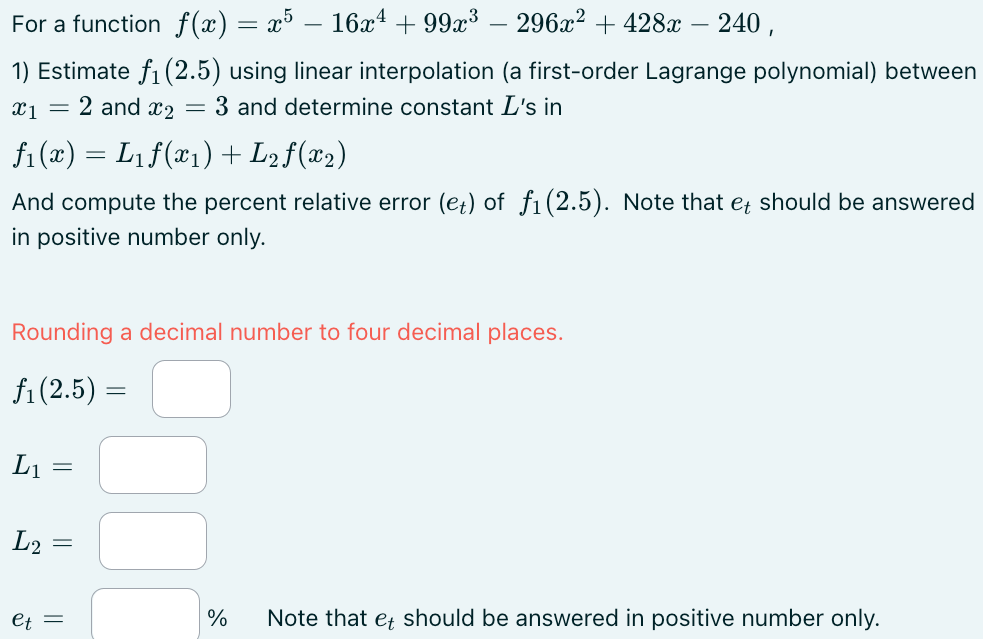

NOTE: $f_1 \left(2\ldotp 5\right)$ is NOT `ftrue` (look at the expression given above)

xtest = 2.5;
f = @(x) x.^5 - (16.*x.^4) + (99.*x.^3) - (296.*x.^2) + (428.*x) - 240;
x = [2 3];
y = f(x);
ftrue = f(xtest);
ftest = Lagrange(x, y, xtest)
et = abs((ftrue - ftest) / ftrue) * 100

### 3.2

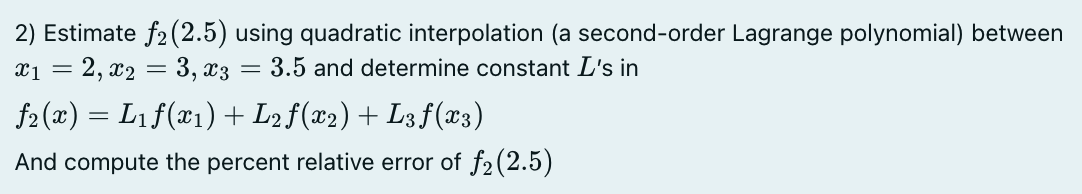

NOTE: $f_2 \left(2\ldotp 5\right)$ is NOT `ftrue` (look at the expression given above)

xtest = 2.5;
x = [2 3 3.5];
f = @(x) x.^5 - 16*x.^4 + 99*x.^3 - 296*x.^2 + 428*x - 240;
y = f(x);
y2lagtest = round(Lagrange(x, y, xtest), 4)
et2 = abs((ftrue - y2lagtest) / ftrue) * 100

### 3.3

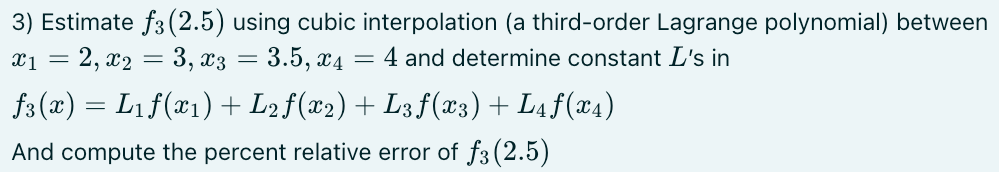

NOTE: $f_3 \left(2\ldotp 5\right)$ is NOT `ftrue` (look at the expression given above)

x = [2 3 3.5 4];
y = f(x);
y3lagtest = Lagrange(x, y, xtest)
et3 = abs((ftrue - y3lagtest) / ftrue) * 100

## Q4 [CORRECT]

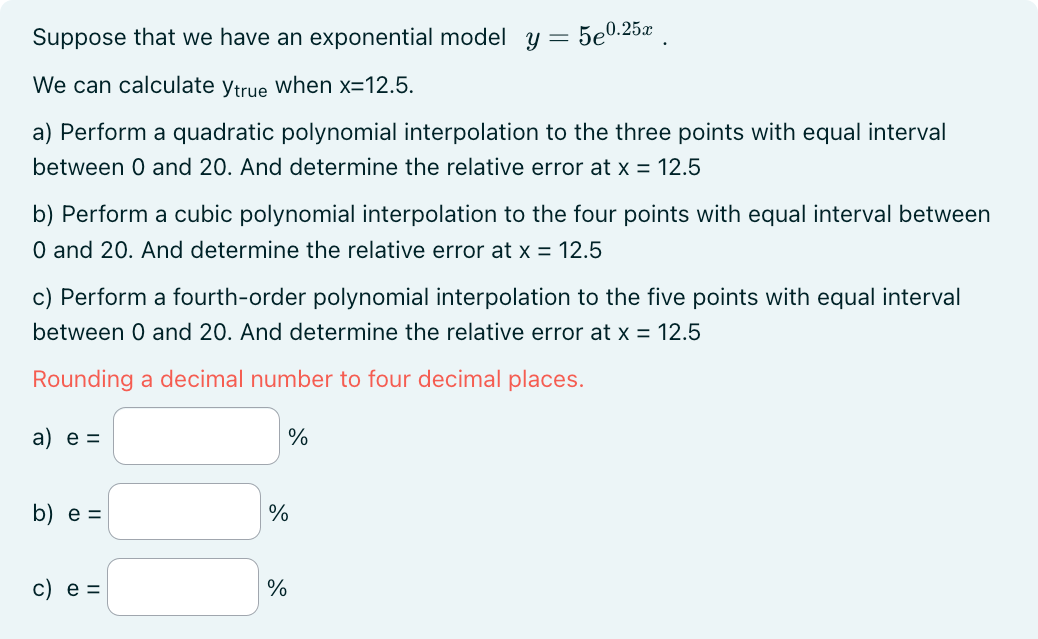

f = @(x) 5*exp(0.25*x);
xtest = 12.5;
ytrue = f(xtest);

### 4a

xxA = linspace(0, 20, 3);
ypredA = Newtint(xxA, f(xxA), xtest);
etA = abs((ytrue - ypredA) / ytrue) * 100

### 4b

xxB = linspace(0, 20, 4);
ypredB = Newtint(xxB, f(xxB), xtest);
etB = abs((ytrue - ypredB) / ytrue) * 100

### 4c

xxB = linspace(0, 20, 5);
ypredB = Newtint(xxB, f(xxB), xtest);
etB = abs((ytrue - ypredB) / ytrue) * 100

## Q5 [WRONG]

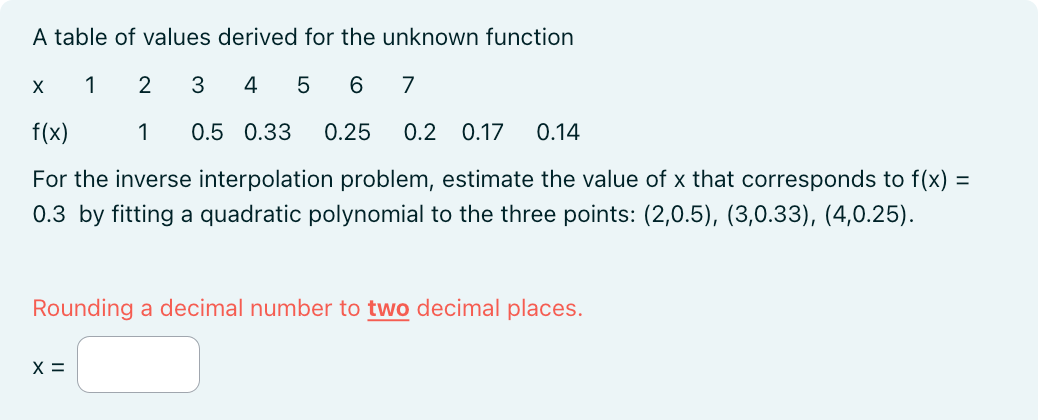

x = [1   2   3    4    5   6    7   ];
y = [1   0.5 0.33 0.25 0.2 0.17 0.14];
ytest = 0.3;
chosenx = [2   3    4];
choseny = [0.5 0.33 0.25];
q5_xpredinv = round(Newtint(choseny, chosenx, ytest), 2) % 3.3400